% 物理量
c0 = 3*1e8;
f0 = 10e9;% 工作频点（Hz）
lambda0 = c0/(f0);
beta0  = 2*pi/lambda0;
k0 = 2*pi/lambda0;

% 间距、孔径、数量
% 确定数量和间距，如何选取孔径大小
% 阵列量
Nx  = 15;% x方向单元个数
Ny = 15;% y方向单元个数
dx = 0.5*lambda0;% x方向单元间距
dy = 0.5*lambda0;% y方向单元间距
L = Nx * dx / 2;
Lx = L;
Ly = L;

% 建立坐标系
% 创建网格
resolution = 5;
[theta, phi] = meshgrid(linspace(-90, 90, 181 * resolution), linspace(0, 360, 361 * resolution));

% 生成周期点坐标。
xPos = -dx*(Nx-1)/2:dx:dx*(Nx-1)/2;
yPos = -dy*(Ny-1)/2:dy:dy*(Ny-1)/2;
periodic_points = [];
for xpos_ = xPos
    for ypos_ = yPos  
        if norm([xpos_, ypos_]) <= L
            periodic_points = [periodic_points; xpos_, ypos_];
        end
    end
end
size(periodic_points)

ans =    177     2



hyperuniform_points_normed = hyperuniform_points * L;


% 选择点
points = hyperuniform_points_normed;
N = size(points, 1);
K = 50;
theta_exc = rad2deg(asin(lambda0 /f/L * sqrt(K)))

theta_exc = 70.5288


min_distance = inf;

% 计算所有点对之间的距离
for i = 1:N-1
    for j = i+1:N
        % 计算两点之间的欧几里得距离
        distance = sqrt(sum((points(i,:) - points(j,:)).^2));
        
        % 更新最小距离
        if distance < min_distance
            min_distance = distance;
        end
    end
end
min_distance/lambda0

ans = 0.1815

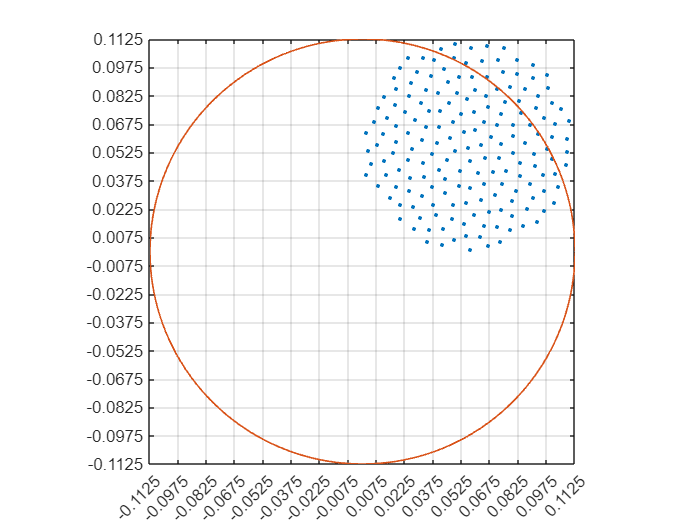

% 绘制点分布
figure;
scatter(points(:, 1), points(:, 2), 50, '.');
axis equal;  
xlim([-Lx, Lx]);
ylim([-Ly, Ly]);

% 获取当前 X 轴和 Y 轴的数据范围
xlims = xlim; % 获取 X 轴限制
ylims = ylim; % 获取 Y 轴限制

% 定义你想要的网格数量（例如，每个方向上 20 条线）
numGridLinesX = Nx;
numGridLinesY = Ny;

% 计算间隔
intervalX = diff(xlims) / numGridLinesX;
intervalY = diff(ylims) / numGridLinesY;

% 设置 X 轴和 Y 轴的刻度位置
xticks(xlims(1):intervalX:xlims(2));
yticks(ylims(1):intervalY:ylims(2));

% 绘制边界
hold on;
theta_ = 0:0.01:2*pi;
x_circle = L * cos(theta_);
y_circle = L * sin(theta_);
plot(x_circle, y_circle, 'LineWidth', 1);
hold off;

% 确保网格可见
grid on;
box on;

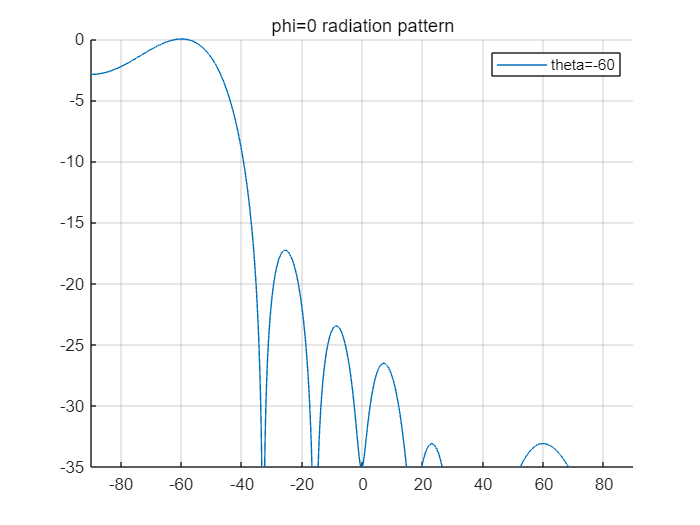

% 反射阵
phiScanDeg = 0;
thetaScanDeg_array = [0,-20,-40,-60];
% 生成uv
u = [sind(theta).*cosd(phi), sind(theta).*sind(phi), zeros(size(theta, 1), size(theta, 2))];
ux = sind(theta).*cosd(phi);
uy = sind(theta).*sind(phi);

% 基础反射阵列参数
rf = [0,0, sqrt(2) * Ny * dy];
qe = 0;
qf = 0;
phase0 = 0;

figure ;
hold on;

a = 0;% 选择多个角度
for thetaScanDeg = -60
% 扫描角
    F = zeros(size(theta, 1),size(theta, 2));
    u0 = [sind(thetaScanDeg)*cosd(phiScanDeg), sind(thetaScanDeg)*sind(phiScanDeg), 0];
    for n = 1:size(points, 1)
        rn = [points(n,:),0];
        c = rn - rf;
        if norm(rn) == 0
            theta_fn = 0;
        else 
            theta_fn = acos(dot(-rn,c) / (norm(rn)*norm(c))) - pi/2;
        end
        An = cosd(theta) .^ qe .* exp(1j * k0 * (rn(1) * ux + rn(2) * uy));
        Rn = norm(rn - rf);
        phase_n = k0 * (Rn - dot(rn, u0)) + phase0; 
        I = cos(theta_fn) .^ qf * exp(-1j * k0 * Rn) * abs(cos(theta_fn) .^ qe) * exp(1j * phase_n);
        F = F + An * I;
    end
    
    % 方向图绘制, 辐射功率方向图
    intensity_pattern = abs(F) .^ 2; % 计算每个点的模值
    if thetaScanDeg == 0
        max_intensity_pattern = max(intensity_pattern(:));
    end
    if a ~= 1
        max_intensity_pattern = max(intensity_pattern(:)); 
    end
    normalized_intensity_pattern = intensity_pattern / max_intensity_pattern; % 归一化处理
    dB_intensity_pattern = 10 * log10(normalized_intensity_pattern);
    
    plot(linspace(-90, 90, 181 * resolution), dB_intensity_pattern(1, :), 'DisplayName', "theta=" + num2str(thetaScanDeg));
    title("phi=0 radiation pattern");
    xlim([-90, 90]);
    ylim([-35, 0]);
end
hold off;
legend;
grid on;

% % 相控阵
% F = zeros(size(theta, 1),size(theta, 2));
% for n = 1:N
%     rn = [points(n,:),0];
%     F = F + exp(1j * k0 * (rn(1) * ux + rn(2) * uy));
% end